# Data Processing - Remove Regeneration

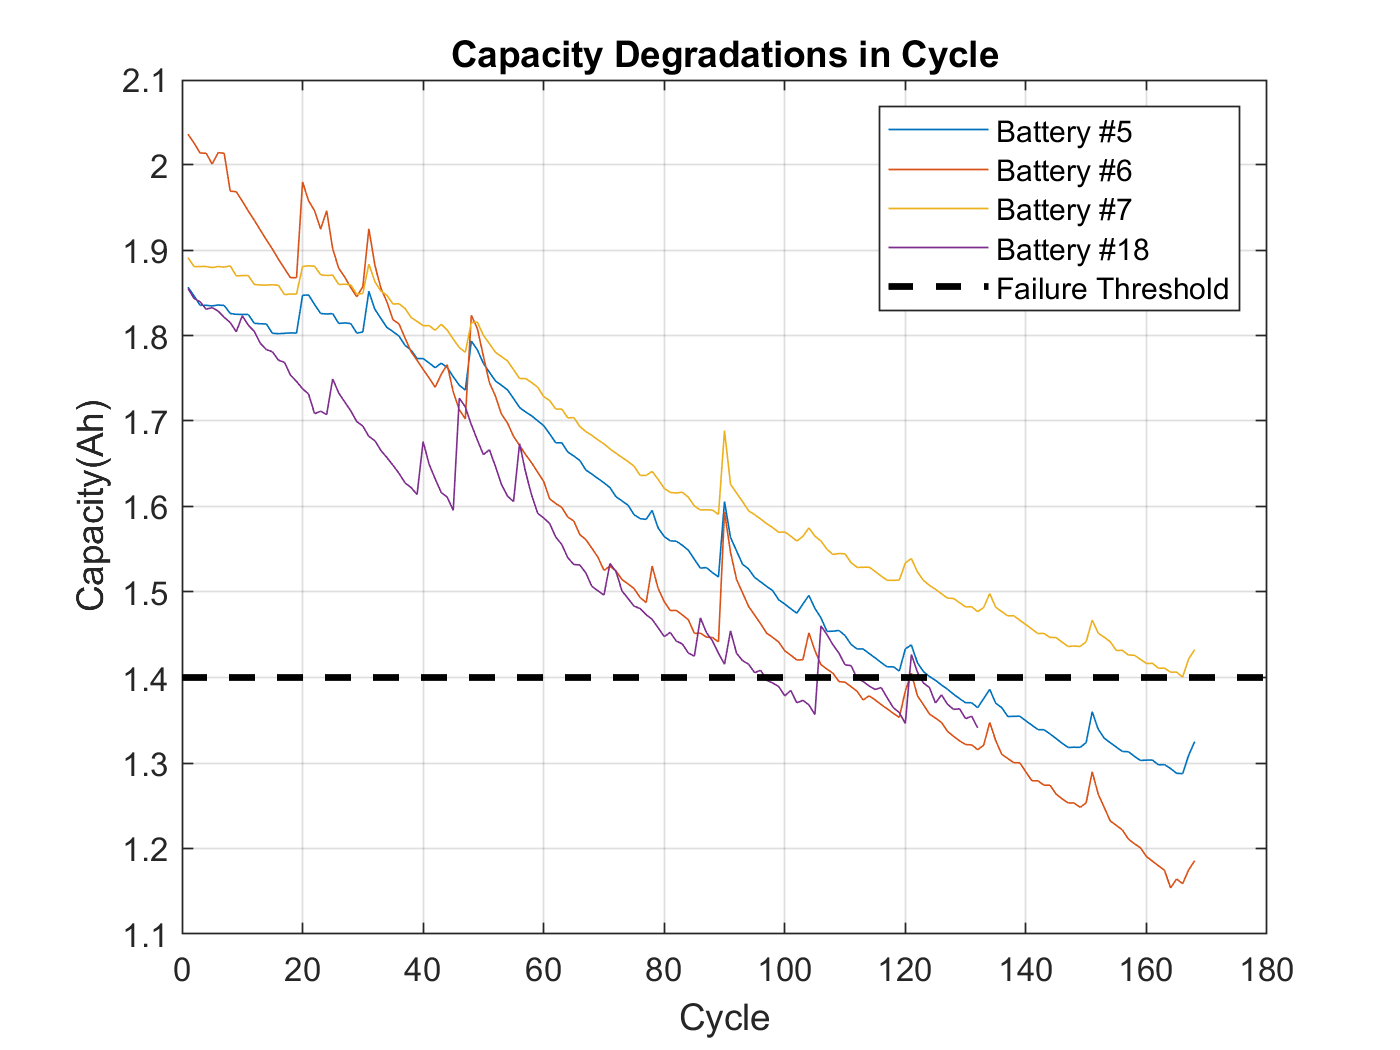

clear
close all

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 
BAT4 =B0018; 

cap05 = extract_discharge(BAT1);
cap06 = extract_discharge(BAT2);
cap07 = extract_discharge(BAT3);
cap18 = extract_discharge(BAT4);

figure
plot(cap05), hold on, plot(cap06), plot(cap07), plot(cap18)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

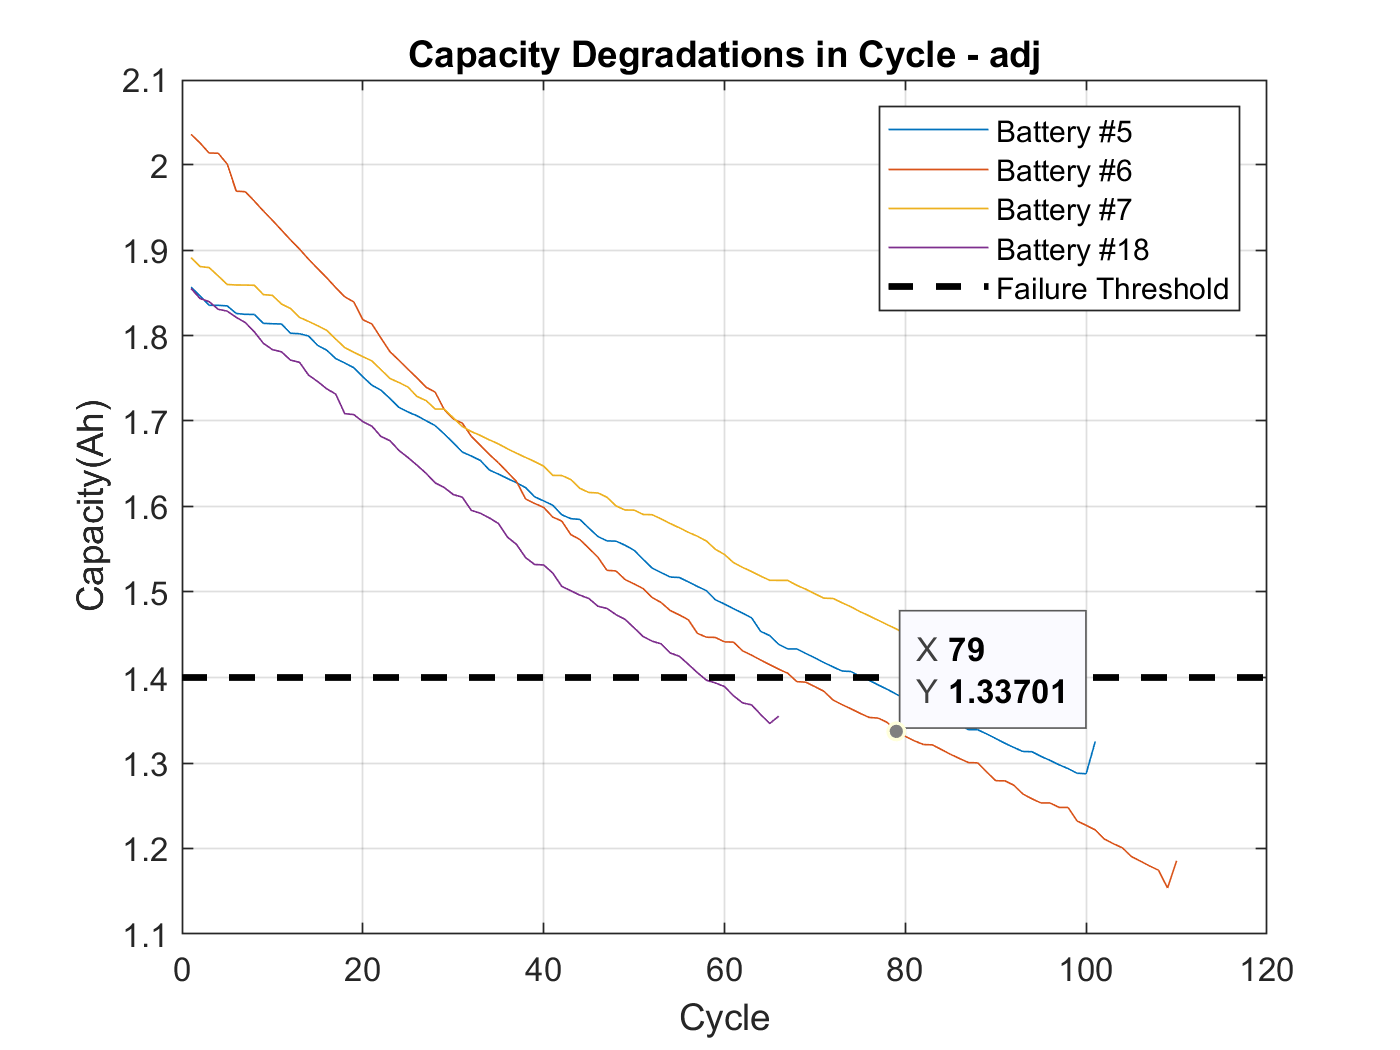


[cap05_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v4(BAT1);
[cap06_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v4(BAT2);
[cap07_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v4(BAT3);
[cap18_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v4(BAT4);

figure
plot(cap05_adj), hold on, plot(cap06_adj), plot(cap07_adj), plot(cap18_adj)
plot(0:120, 1.4*ones(1, 121),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle - adj')


initCap  = min ( [ cap05_adj(1)  cap06_adj(1) cap07_adj(1) cap18_adj(1) ]  ) 

initCap = 1.8550



cap05_adj1 = match_initial_capacity ( cap05_adj, initCap);
cap06_adj1 = match_initial_capacity ( cap06_adj, initCap);
cap07_adj1 = match_initial_capacity ( cap07_adj, initCap);
cap18_adj1 = match_initial_capacity ( cap18_adj, initCap);
maxCycle  = max ( [ length(cap05_adj1)  length(cap06_adj1) length(cap07_adj1) length(cap18_adj1) ]  ) 

maxCycle = 100

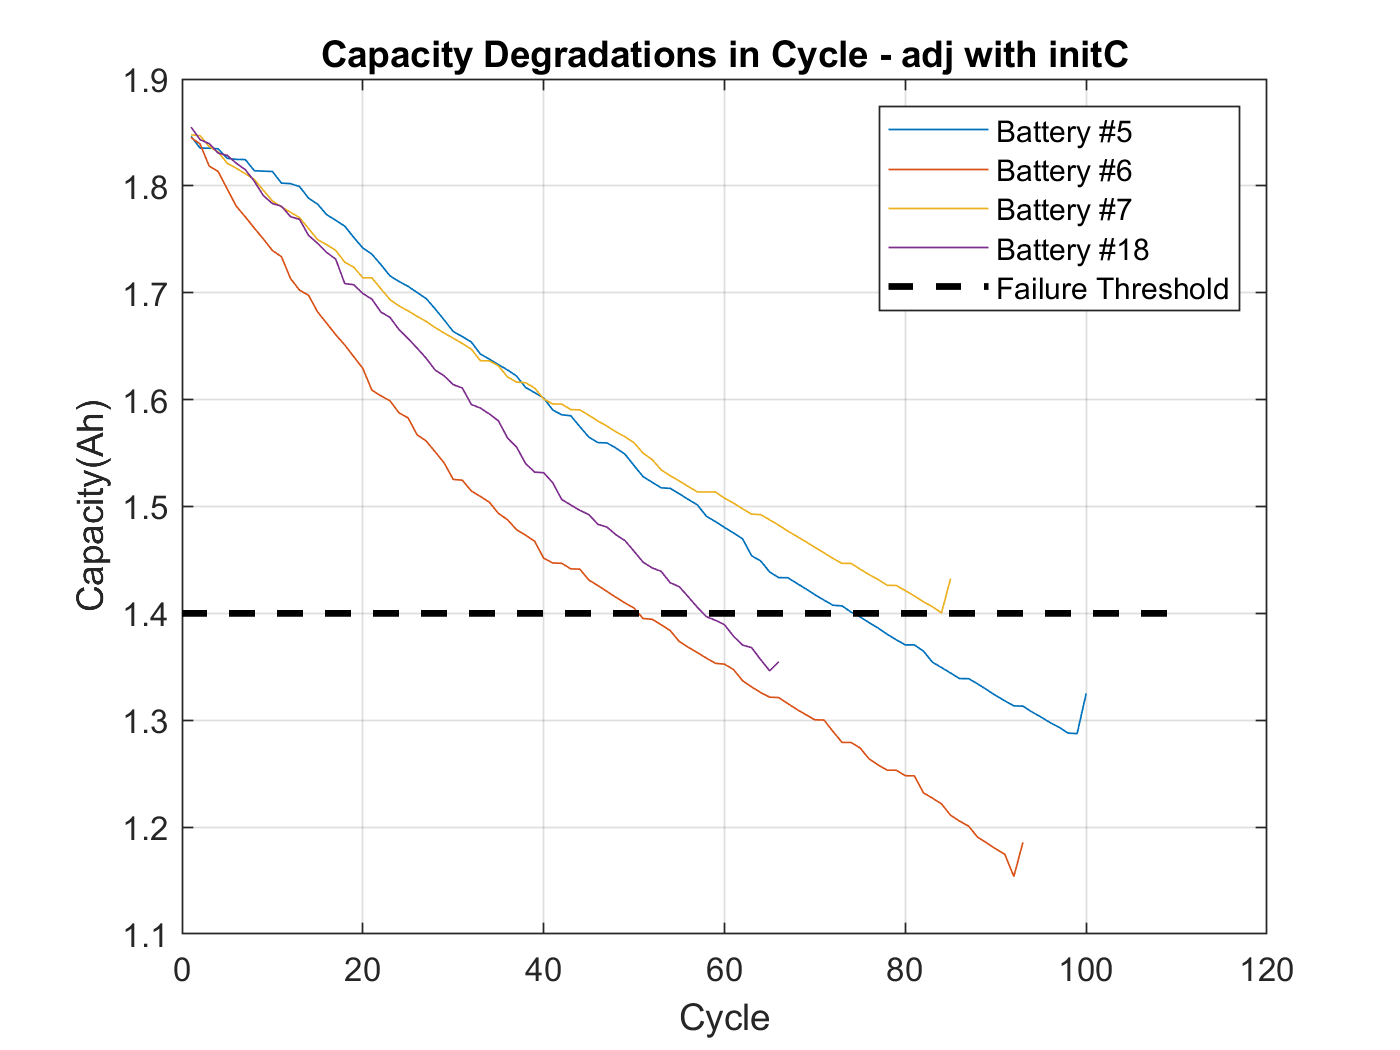

maxCycle = maxCycle + 10;

figure
plot(cap05_adj1), hold on, plot(cap06_adj1), plot(cap07_adj1), plot(cap18_adj1)
plot(0:maxCycle-1, 1.4*ones(1, maxCycle),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle - adj with initC')

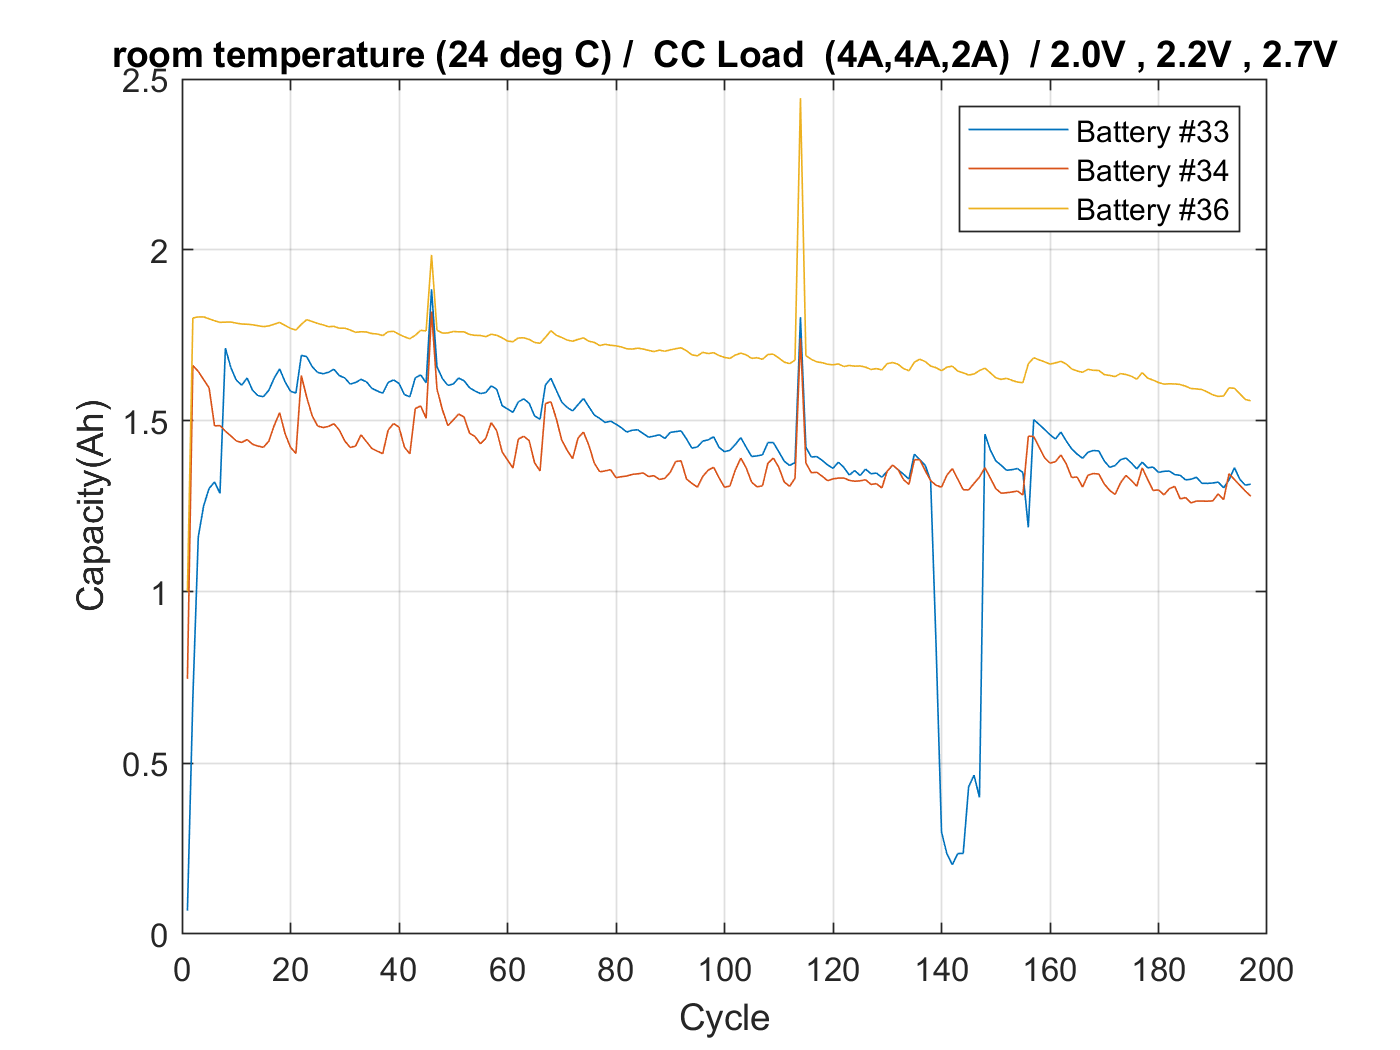


load B0033.mat
load B0034.mat
load B0036.mat

cap33 = extract_discharge(B0033);
cap34 = extract_discharge(B0034);
cap36 = extract_discharge(B0036);


cycleNumber = length(cap33);

figure
plot(cap33), hold on, plot(cap34), plot(cap36)

hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #33', 'Battery #34', 'Battery #36')
title('room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V')

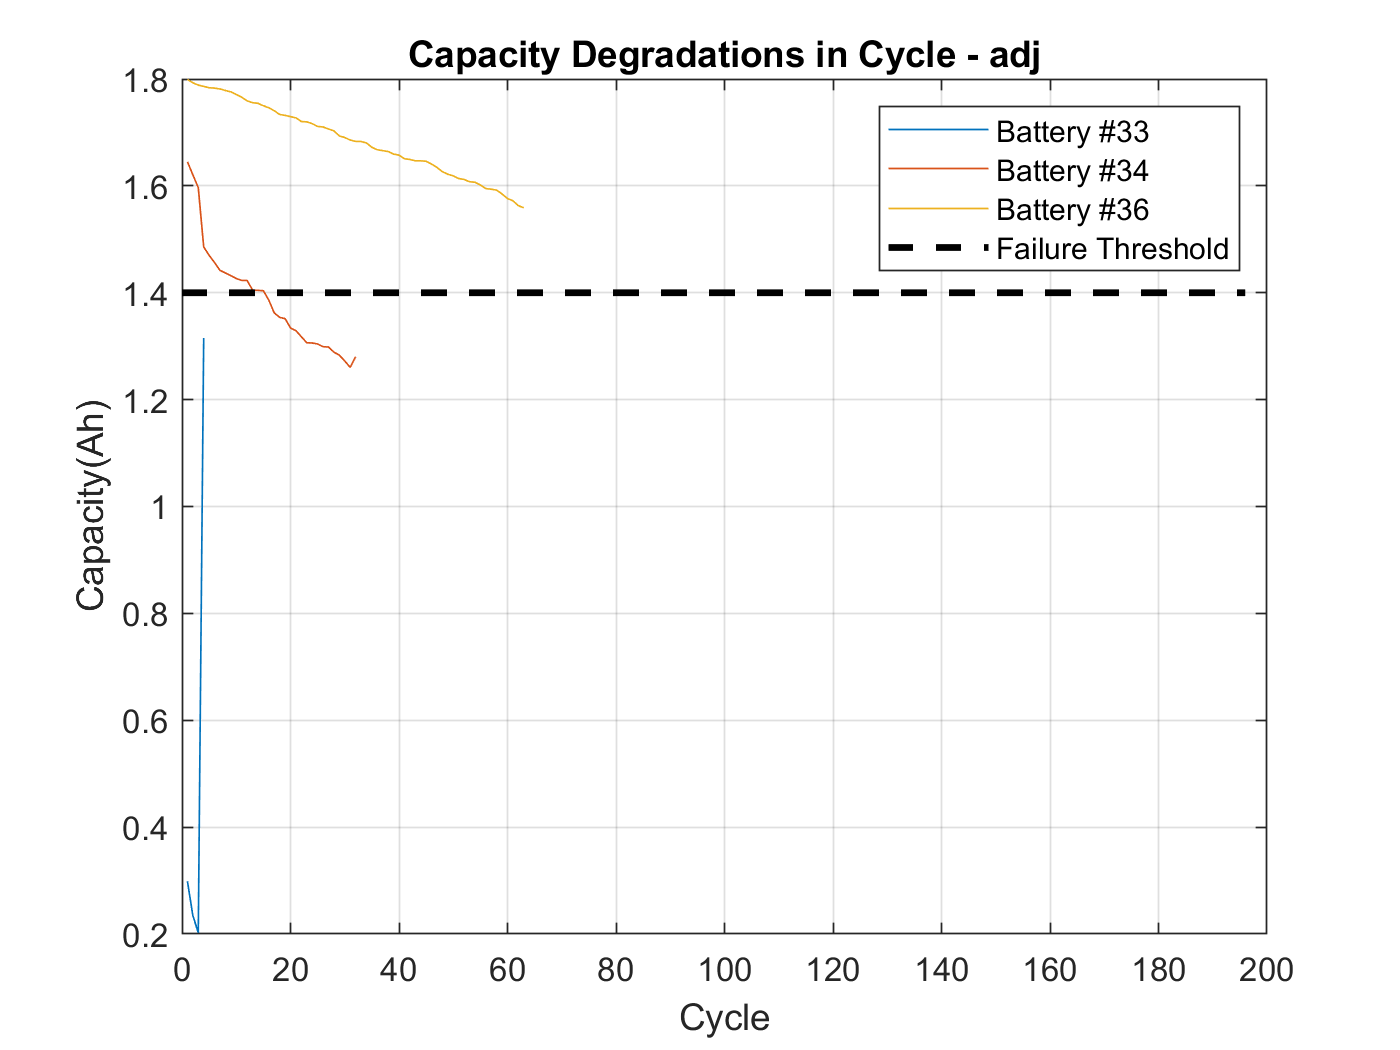


[cap33_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v5(B0033,7);
% 0.0684    0.6896    1.1611    1.2529    1.3029    1.3219    1.2885    1.7132 
[cap34_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v5(B0034,1);
[cap36_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v5(B0036,2);

figure
plot(cap33_adj), hold on, plot(cap34_adj), plot(cap36_adj)
plot(0:cycleNumber-1, 1.4*ones(1, cycleNumber),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #33', 'Battery #34', 'Battery #36', 'Failure Threshold')
title('Capacity Degradations in Cycle - adj')


initCap  = min ( [ cap33_adj(1)  cap34_adj(1) cap36_adj(1) ]  ) 

initCap = 0.2987



cap33_adj1 = match_initial_capacity ( cap33_adj, initCap);
cap34_adj1 = match_initial_capacity ( cap34_adj, initCap);
cap36_adj1 = match_initial_capacity ( cap36_adj, initCap);
maxCycle  = max ( [ length(cap33_adj1)  length(cap34_adj1) length(cap36_adj1)  ]  ) 

maxCycle = 3

maxCycle = maxCycle + 10;

figure
plot(cap33_adj1), hold on, plot(cap34_adj1), plot(cap36_adj1)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #33', 'Battery #34', 'Battery #36')

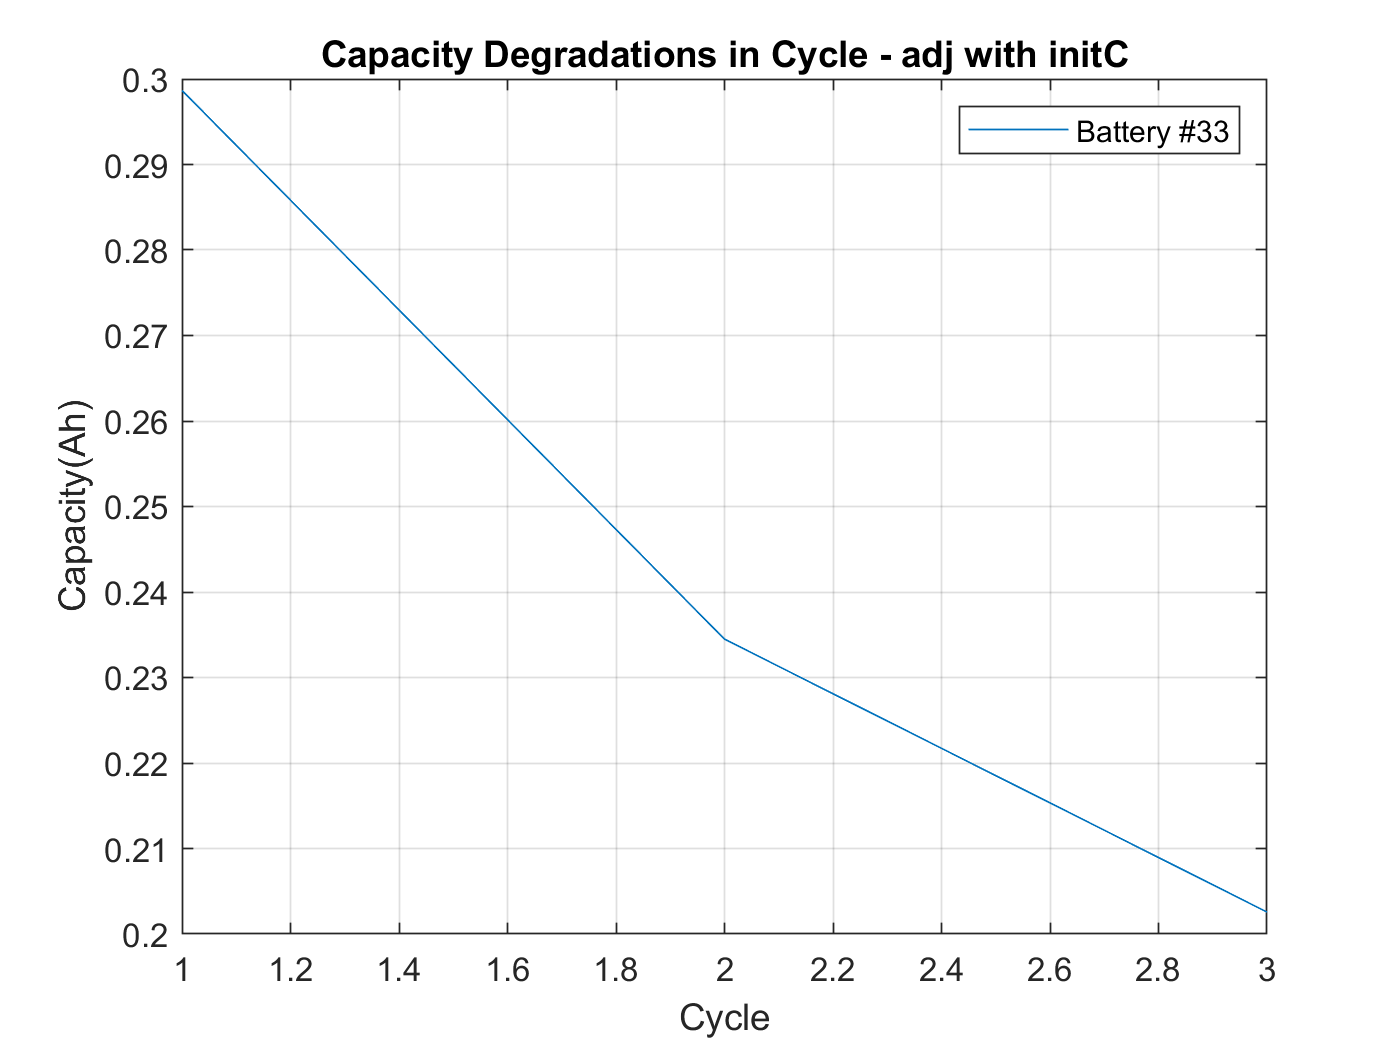

title('Capacity Degradations in Cycle - adj with initC')

maxCycle_adj  = max ( [ length(cap05_adj)  length(cap06_adj) length(cap07_adj) length(cap18_adj) length(cap33_adj)  length(cap34_adj) length(cap36_adj)  ]  ) 

maxCycle_adj = 110

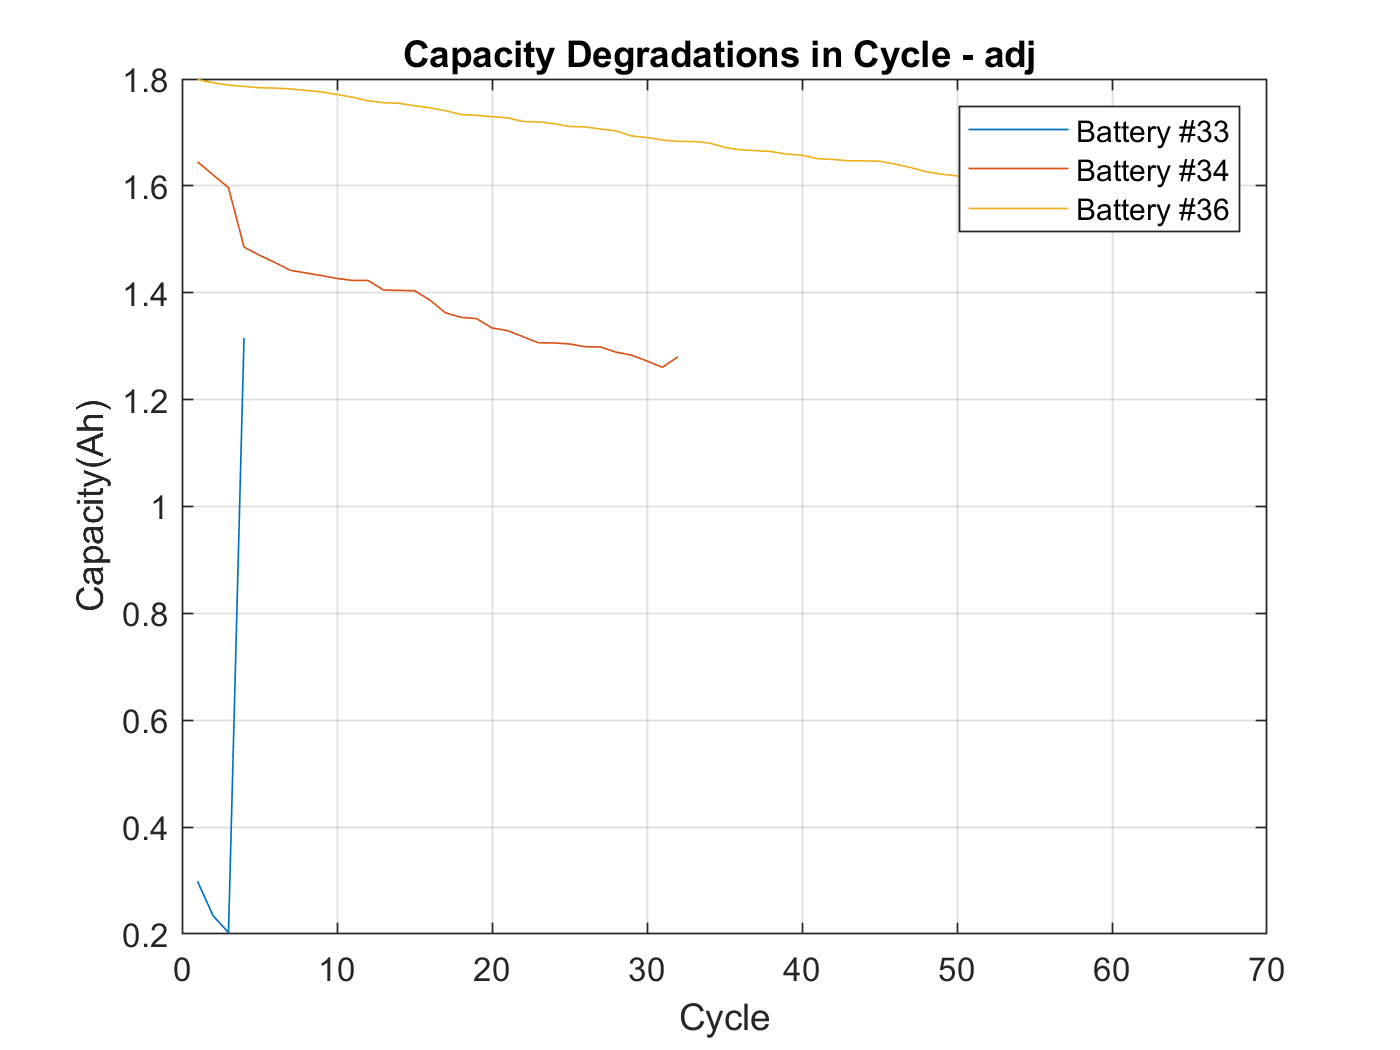


figure
%plot(cap05_adj), hold on, plot(cap06_adj), plot(cap07_adj), plot(cap18_adj)
plot(cap33_adj), hold on,  plot(cap34_adj), plot(cap36_adj)
%plot(cap05_adj), hold on, plot(cap06_adj), plot(cap07_adj), plot(cap18_adj),plot(cap33_adj), plot(cap34_adj), plot(cap36_adj)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
%legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18', 'Failure Threshold')
legend('Battery #33', 'Battery #34', 'Battery #36')
%legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Battery #33', 'Battery #34', 'Battery #36', 'Failure Threshold')
title('Capacity Degradations in Cycle - adj ')






initCap  = min ( [ cap05_adj(1)  cap06_adj(1) cap07_adj(1) cap18_adj(1) cap36_adj(1)  ]  ) 

initCap = 1.7989



cap05_adj1 = match_initial_capacity ( cap05_adj, initCap);
cap06_adj1 = match_initial_capacity ( cap06_adj, initCap);
cap07_adj1 = match_initial_capacity ( cap07_adj, initCap);
cap18_adj1 = match_initial_capacity ( cap18_adj, initCap);
cap33_adj1 = match_initial_capacity ( cap33_adj, initCap);
cap34_adj1 = match_initial_capacity ( cap34_adj, initCap);
cap36_adj1 = match_initial_capacity ( cap36_adj, initCap);
maxCycle  = max ( [ length(cap05_adj1)  length(cap06_adj1) length(cap07_adj1) length(cap18_adj1) length(cap36_adj1)  ]  ) 

maxCycle = 89

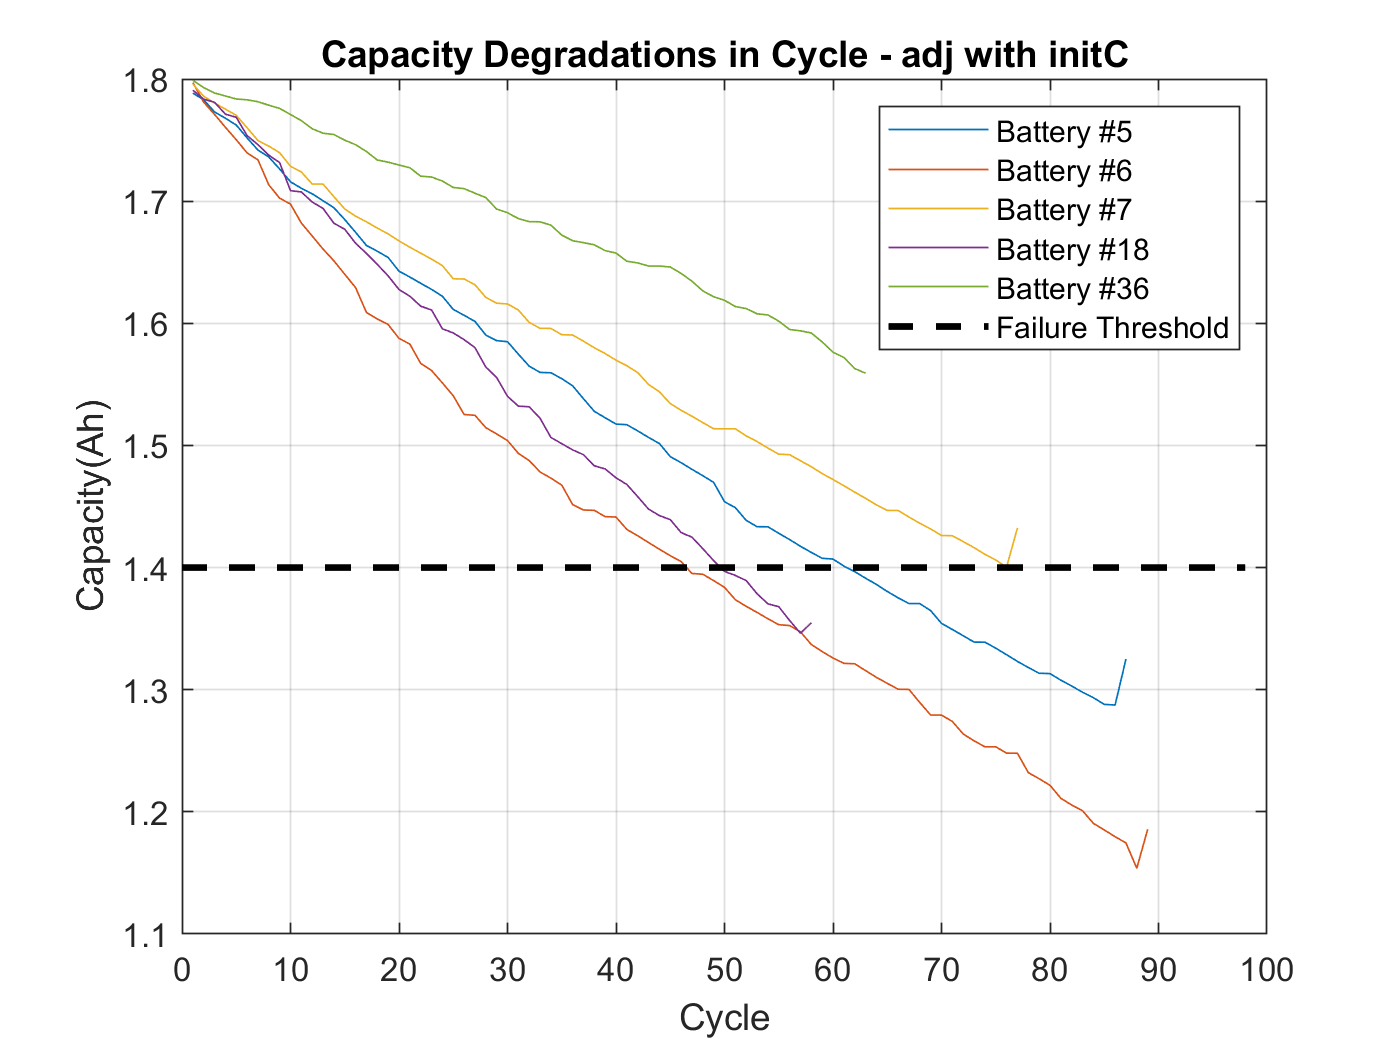

maxCycle = maxCycle + 10;

figure
plot(cap05_adj1), hold on, plot(cap06_adj1), plot(cap07_adj1), plot(cap18_adj1), plot(cap36_adj1)
plot(0:maxCycle-1, 1.4*ones(1, maxCycle),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Battery #36', 'Failure Threshold')
title('Capacity Degradations in Cycle - adj with initC')

36 - 2A  4.2 to 2.7V

7   - 2A  4.2 to 2.2v = 이상하다 

5 - 2A  4.2 to 2.7V

18 - 2A  4.2 to 2.5v

6  - 2A  4.2 to 2.5v

2A  /  2.7V, 2.5V, 2.2V and 2.5V

#### 현재 상태에서는 배터리 5와 6으로만 테스트 하자.

#### 테스트셋은 배터리5에서  1.7 1.6 1.5Ah 에서 이후 테이타를 배러티6으로 변경

#### 테스트셋은 배터리6에서  1.7 1.6 1.5Ah 에서 이후 테이타를 배러티5으로 변경

#### 기존 세트 2개  + 변경된 세트 6개 

43 deg C / CC Load 4A /  **2.0V, 2.2V, 2.5V and 2.7V **

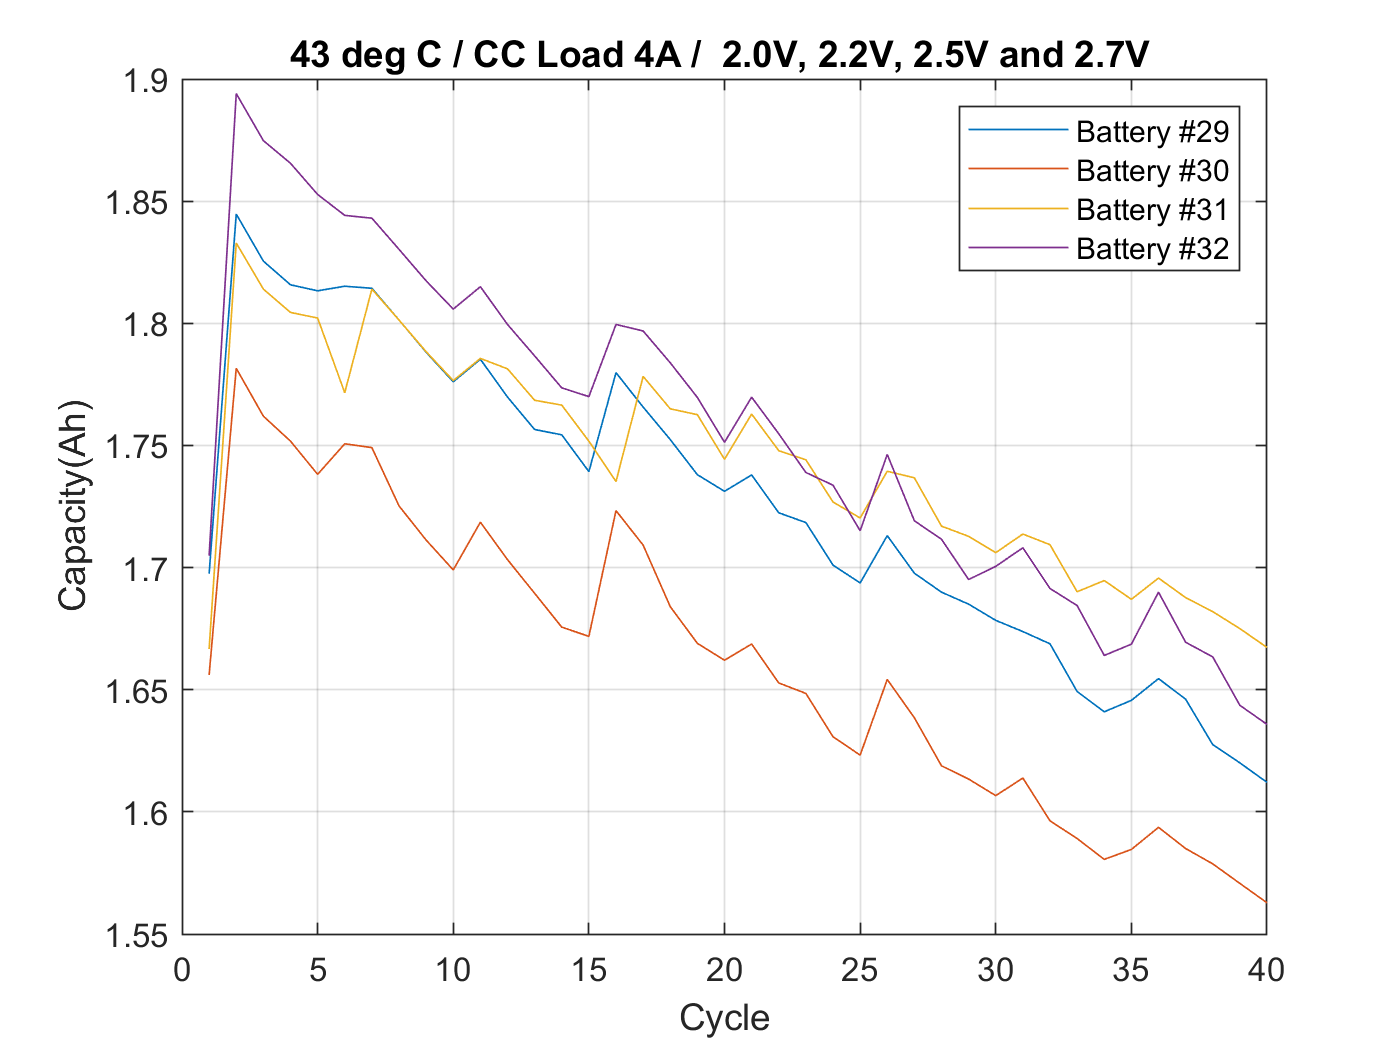

load B0029.mat
load B0030.mat
load B0031.mat
load B0032.mat
cap29 = extract_discharge(B0029);
cap30 = extract_discharge(B0030);
cap31 = extract_discharge(B0031);
cap32 = extract_discharge(B0032);

cycleNumber = length(cap29);

figure
plot(cap29), hold on, plot(cap30), plot(cap31), plot(cap32)

hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #29', 'Battery #30', 'Battery #31', 'Battery #32')
title('43 deg C / CC Load 4A /  2.0V, 2.2V, 2.5V and 2.7V ')

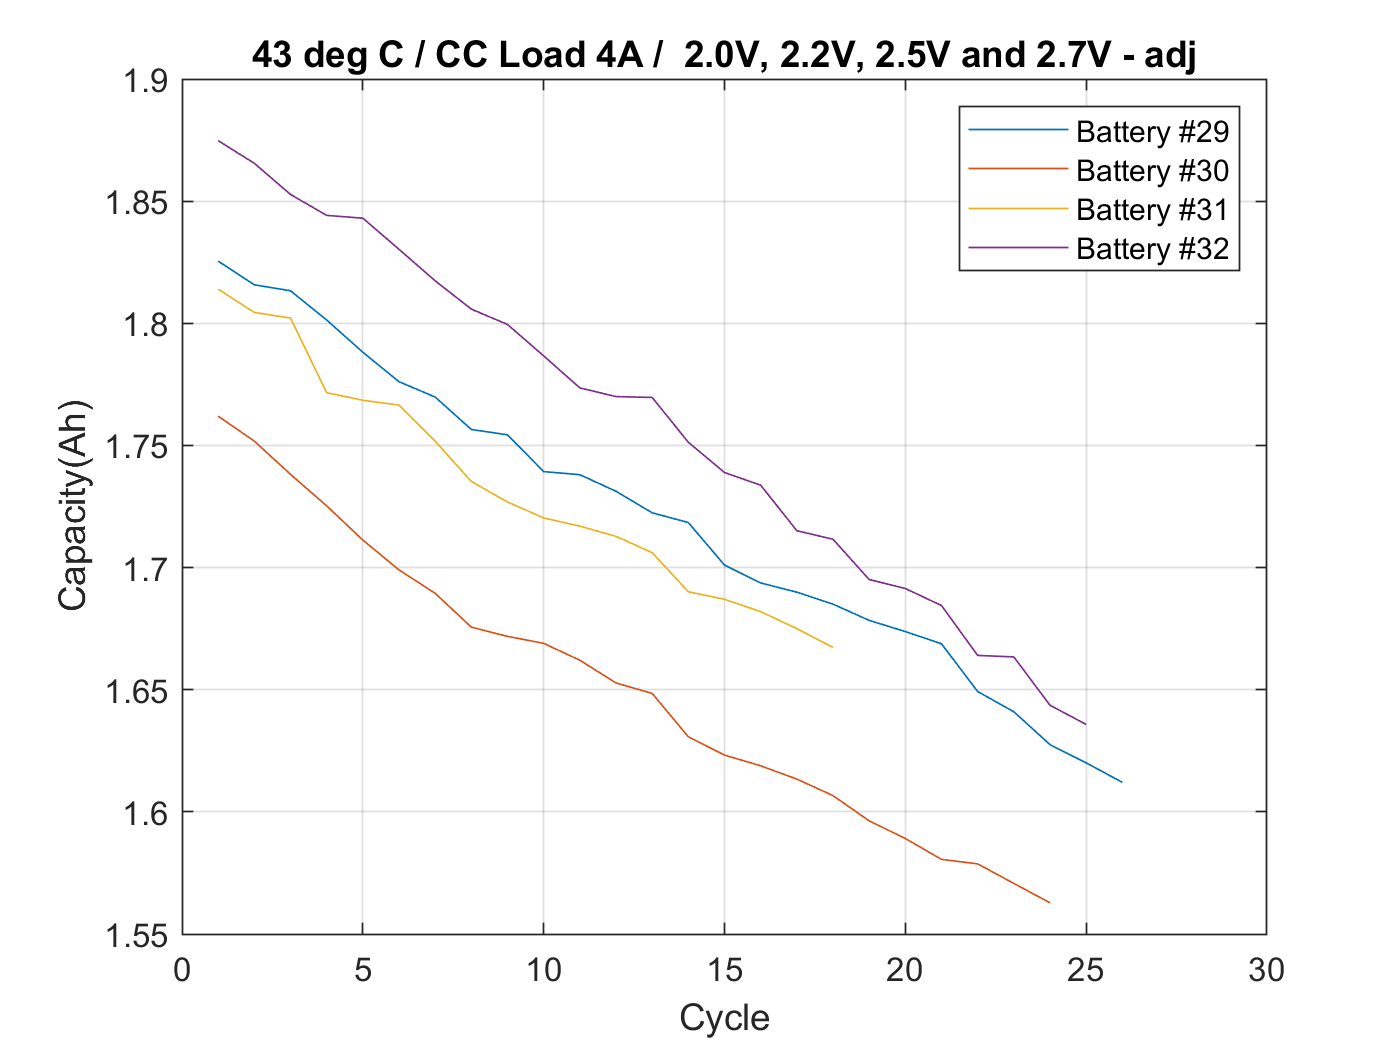


[cap29_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v5(B0029,1);
[cap30_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v5(B0030,1);
[cap31_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v5(B0031,1);
[cap32_adj,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v5(B0032,1);

figure
plot(cap29_adj), hold on, plot(cap30_adj), plot(cap31_adj),plot(cap32_adj),
%plot(0:cycleNumber-1, 1.4*ones(1, cycleNumber),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #29', 'Battery #30', 'Battery #31', 'Battery #32')
title('43 deg C / CC Load 4A /  2.0V, 2.2V, 2.5V and 2.7V - adj')


initCap  = min ( [ cap29_adj(1)  cap30_adj(1) cap31_adj(1) cap32_adj(1)  ]  ) ;
cap29_adj1 = match_initial_capacity ( cap29_adj, initCap);
cap30_adj1 = match_initial_capacity ( cap30_adj, initCap);
cap31_adj1 = match_initial_capacity ( cap31_adj, initCap);
cap32_adj1 = match_initial_capacity ( cap32_adj, initCap);
maxCycle  = max ( [ length(cap29_adj1)  length(cap30_adj1) length(cap31_adj1)  length(cap32_adj1)  ]  ) 

maxCycle = 24

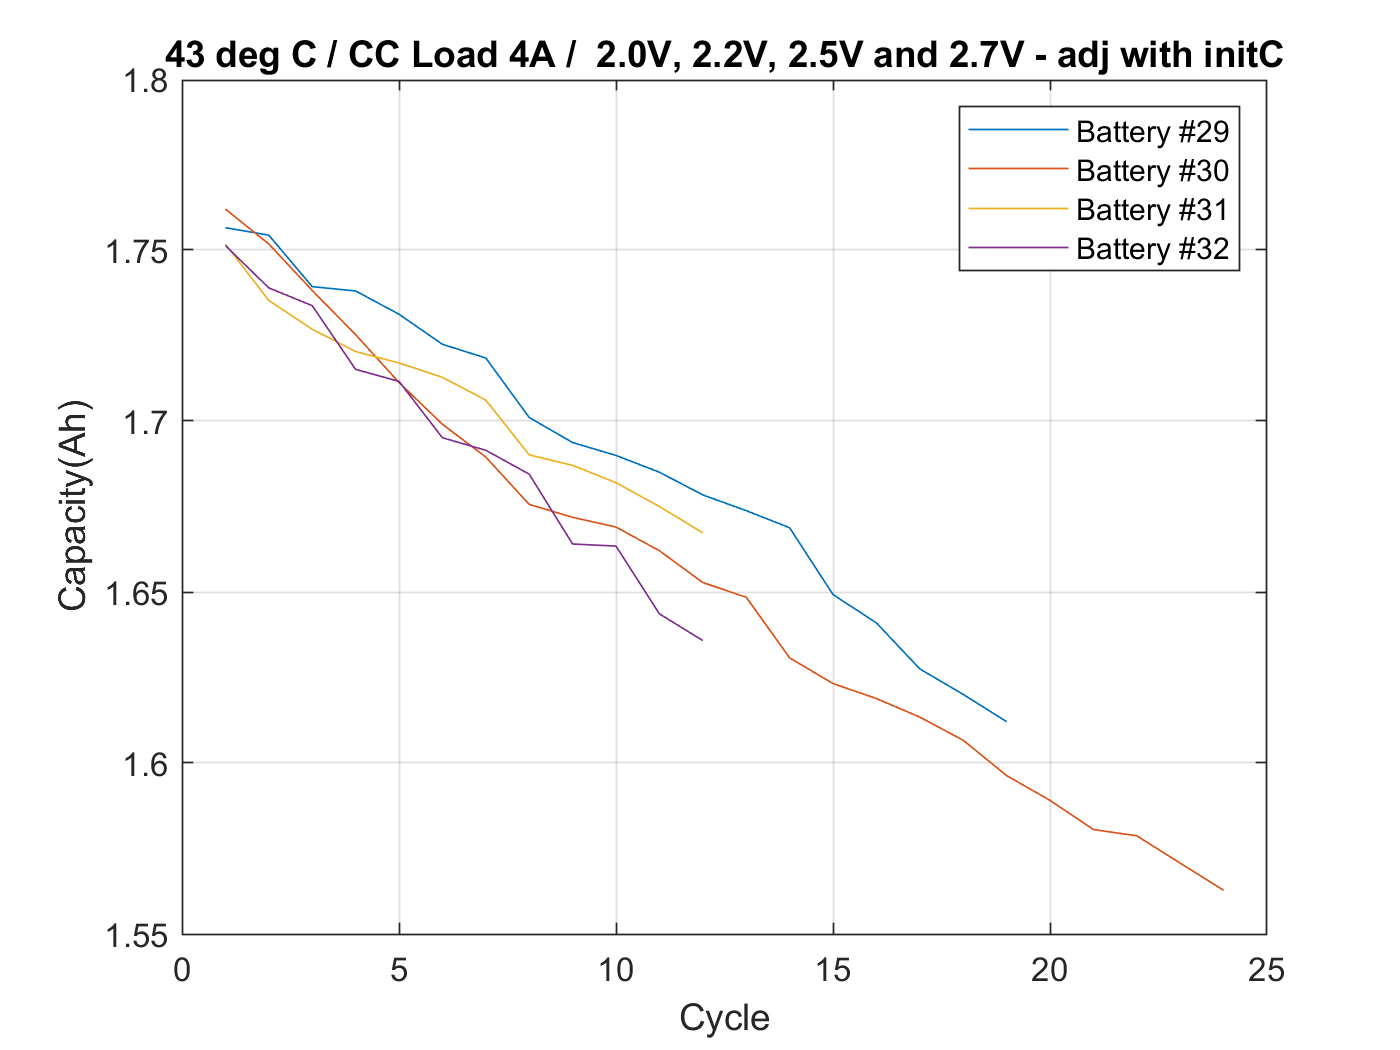

maxCycle = maxCycle + 10;

figure
plot(cap29_adj1), hold on, plot(cap30_adj1), plot(cap31_adj1), plot(cap32_adj1)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #29', 'Battery #30', 'Battery #31', 'Battery #32')
title('43 deg C / CC Load 4A /  2.0V, 2.2V, 2.5V and 2.7V - adj with initC')